clear; clc; close all;

split_percent = 30/31;
split_idx = split_percent * size(features, 2);
X_Train = features(:, 1:split_idx);
Y_Train = labels(:, 1:split_idx);
X_Test = features(:, split_idx+1:end);
Y_Test = labels(:, split_idx+1:end);

dsTrain = MyDataStore(X_Train, Y_Train);
dsTest = MyDataStore(X_Test, Y_Test);
dsTrain, dsTest

dsTrain =   MyDataStore with properties:

    Features: [10×3000000 double]
      Labels: [121×3000000 double]


dsTest =   MyDataStore with properties:

    Features: [10×100000 double]
      Labels: [121×100000 double]


layers = [
    featureInputLayer(2 * M, "Normalization", "none")
    fullyConnectedLayer(150)
    reluLayer
    fullyConnectedLayer(150)
    reluLayer
    fullyConnectedLayer(150)
    reluLayer
    fullyConnectedLayer(150)
    reluLayer
    fullyConnectedLayer(121)
    regressionLayer
    ]

layers =   11×1 Layer array with layers:

     1   ''   Feature Input       10 features
     2   ''   Fully Connected     150 fully connected layer
     3   ''   ReLU                ReLU
     4   ''   Fully Connected     150 fully connected layer
     5   ''   ReLU                ReLU
     6   ''   Fully Connected     150 fully connected layer
     7   ''   ReLU                ReLU
     8   ''   Fully Connected     150 fully connected layer
     9   ''   ReLU                ReLU
    10   ''   Fully Connected     121 fully connected layer
    11   ''   Regression Output   mean-squared-error

% Compile the model with specified loss function
options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs', 15, ...
    'MiniBatchSize', 128, ...
    'Shuffle', 'every-epoch', ...
    'Plots', 'training-progress')

options =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-03
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 15
                   MiniBatchSize: 128
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'every-epoch'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvi

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:14 |         1.81 |          1.6 |          0.0010 |
|       1 |          50 |       00:00:16 |         1.40 |          1.0 |          0.0010 |
|       1 |         100 |       00:00:17 |         1.40 |          1.0 |          0.0010 |
|       1 |         150 |       00:00:18 |         1.39 |          1.0 |          0.0010 |
|       1 |         200 |       00:00:19 |         1.38 |          1.0 |          0.0010 |
|       1 |         250 |       00:00:20 |         1.37 |          0.9 |          0.0010 |
|       1 |         300 |       00:00:21 |         1.36 |         

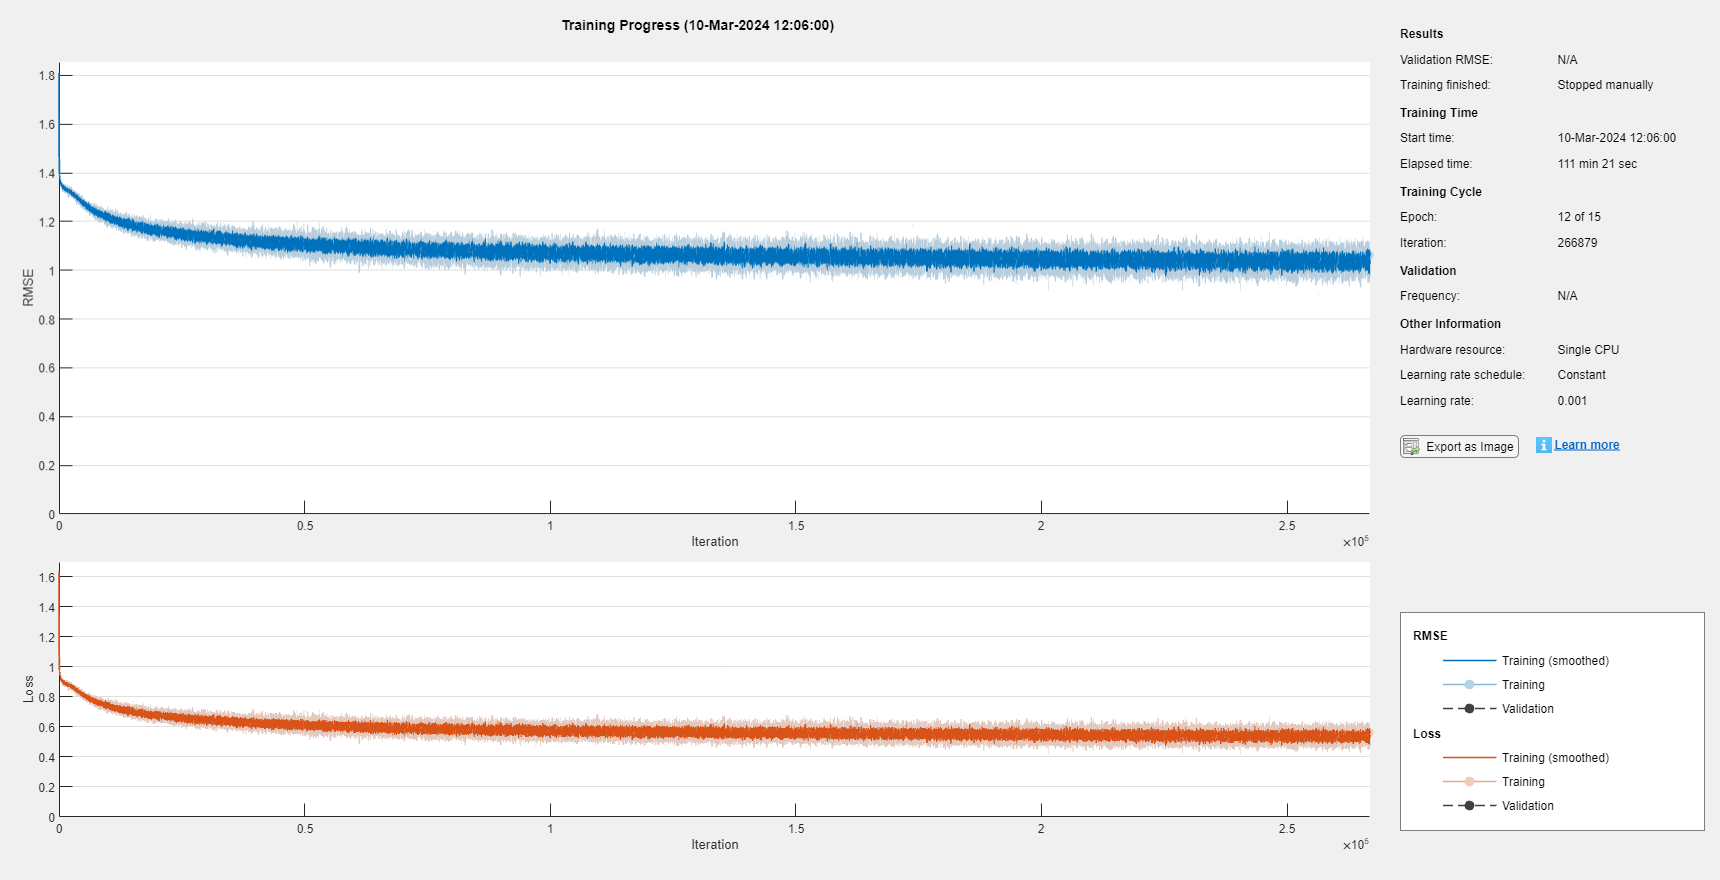

net =   SeriesNetwork with properties:

         Layers: [11×1 nnet.cnn.layer.Layer]
     InputNames: {'input'}
    OutputNames: {'regressionoutput'}


net = trainNetwork(dsTrain, layers, options)

YPred = predict(net, X_Test.').';
E = size(X_Test, 2);
avg_rmse = 0;
for i = 1:E
    avg_rmse = avg_rmse + rmse(YPred(:, i), Y_Test(:, i));
end
avg_rmse = avg_rmse / E

avg_rmse = single
0.0900

# Testing

load OnGrid_Network
addpath('D:\D\Alp\Master ODTÜ\Thesis\DOA\Codes\Direction-of-Arrival');
DOA = FunctionsOfDOA();

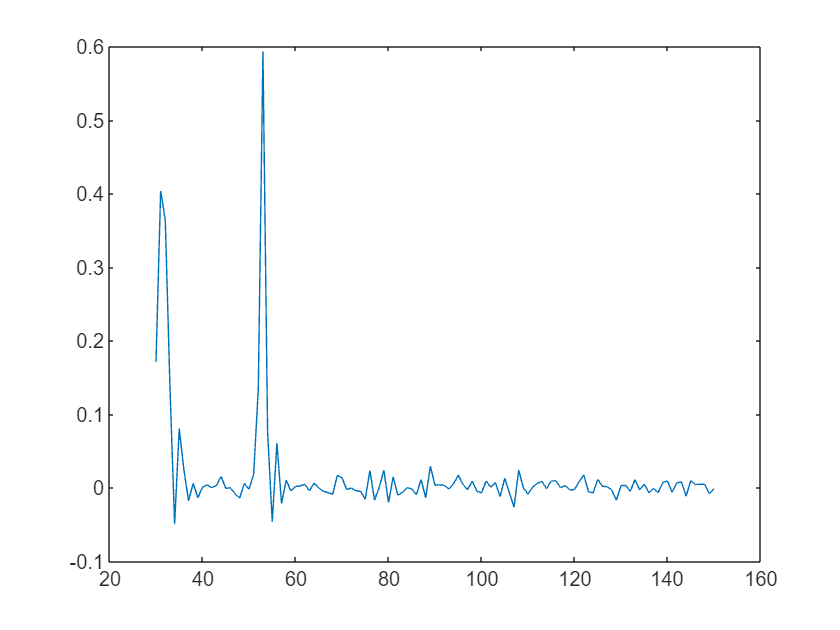

DOA: 32 53


Test(DOA, net);

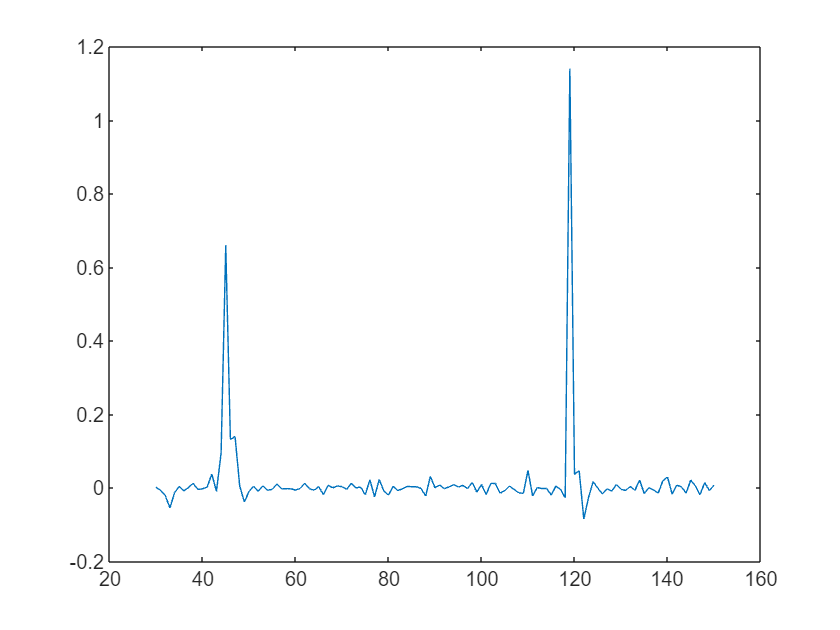

DOA: 44.3589 119.3392


Test(DOA, net);

function Test(DOA, net)
sensor_locations = [0 1 4 7 9];
M = length(sensor_locations);
K = 2;          % # of sources
L = 1;          % # of snapshots
phi_min = 30;
phi_max = 150;
delta_phi = 1;  % angle resolution
label = zeros((phi_max - phi_min)/delta_phi + 1, 1);

doa = (-2 * delta_phi) * ones(1, K);
i = 1;
while true
    temp_angle = phi_min + rand * (phi_max - phi_min);
    temp_array = abs(doa - temp_angle);
    if any(temp_array < delta_phi)
        i = i - 1;
    else
        doa(i) = temp_angle;
    end
    if i == K
        break
    end
    i = i + 1;
end
doa = sort(doa);
rounded_doa = round(doa);

A = DOA.Array_Manifold(0.5, sensor_locations, doa);
s = DOA.Source_Generate(K, L);
idx_label = rounded_doa - phi_min + 1;
label(idx_label) = abs(s);
SNR_dB = 30 * rand;     % min = 0 dB, max = 30 dB
n = DOA.Noise_Generate(SNR_dB, M, L);
y = A * s + n;
feature = [real(y); imag(y)];

s_predicted = predict(net, feature.');
plot(phi_min:delta_phi:phi_max, s_predicted);

msg = "DOA:";
for i = 1:K
    msg = msg + " " + doa(i);
end
disp(msg)
end